# Hierarchical scalar interpolation example

clear ; close all ; path=pwd();
[s,e]=regexp(path,'.+(?=[\\/]{1,2}examples)');
path=path(s:e); addpath(genpath(path)); clear s e path

## 1) Definition of the interpolation tree

From the leaves to the root.

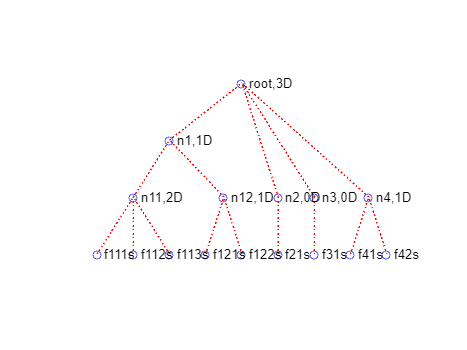

defNode11.Domain = Domain(3);
f111s = VertexFunction(@(a) -a.^2, @(a) -2*a, "f111s");
f112s = VertexFunction(@(a) a.^3, @(a) 3*a.^2, "f112s");
f113s = VertexFunction(@(a) 0.1*a, @(a) 0.1*ones(size(a)), "f113s");
defNode11.Children = [f111s,f112s,f113s];
defNode11.Label = "n11"; % Neveu convention (any unique labeling is possible)
defNode11.Penalization = Penalization("simp",2);
Node11 = Interpolation(defNode11);

defNode12.Domain = Domain(2);
f121s = VertexFunction(@(a) -a.^2, @(a) -2*a, "f121s");
f122s = VertexFunction(@(a) a.^3, @(a) 3*a.^2, "f122s");
defNode12.Children = [f121s,f122s];
defNode12.Label = "n12";
defNode12.Penalization = Penalization("ramp",2);
Node12 = Interpolation(defNode12);

defNode1.Domain = Domain(2);
defNode1.Children = [Node11,Node12];
defNode1.Label = "n1";
defNode1.Penalization = Penalization("ramp_inv",2);
Node1 = Interpolation(defNode1);

defNode2.Domain = Domain(1);
defNode2.Children = VertexFunction(@(a) -0.4*a.^2, @(a) -0.8*a, "f21s");
defNode2.Label = "n2";
Node2 = Interpolation(defNode2);


% singleton domains to keep homogeneous children of Node 0
defNode3.Domain = Domain(1);
defNode3.Children = VertexFunction(@(a) 0.1*a.^2, @(a) 0.2*a, "f31s");
defNode3.Label = "n3";
Node3 = Interpolation(defNode3);


defNode4.Domain = Domain(2);
f41s = VertexFunction(@(a) a, @(a) ones(size(a)), "f41s");
f42s = VertexFunction(@(a) 0.1*a.^3, @(a) 0.3*a.^2, "f42s");
defNode4.Children = [f41s,f42s];
defNode4.Label = "n4";
defNode4.Penalization = Penalization("ramp_inv",2);
Node4 = Interpolation(defNode4);

% Finally, we define the root and the all tree

defNode0.Domain = Domain("tetra");
defNode0.Children = [Node1,Node2,Node3,Node4];
defNode0.Label = "root";
defNode0.Penalization = Penalization("lukas",2);
interpHierarchical = Interpolation(defNode0);

interpHierarchical.plotTree();

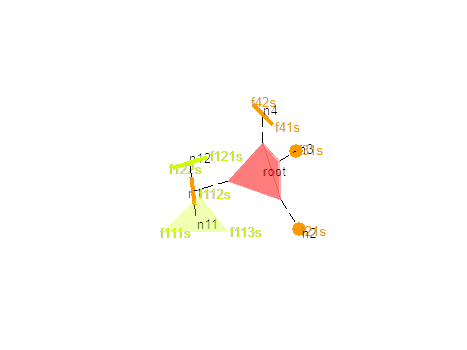

figure()
interpHierarchical.plot();

## 4) Definition of the variables

### a) Coordinates in the polygon

n = 1e2; % number of evaluation points
x = interpHierarchical.initializeVariable(n,"rand",0.6)

x = struct with fields:
    root: [100×3 double]
      n1: [100×1 double]
     n11: [100×2 double]
     n12: [100×1 double]
      n2: [100×0 double]
      n3: [100×0 double]
      n4: [100×1 double]


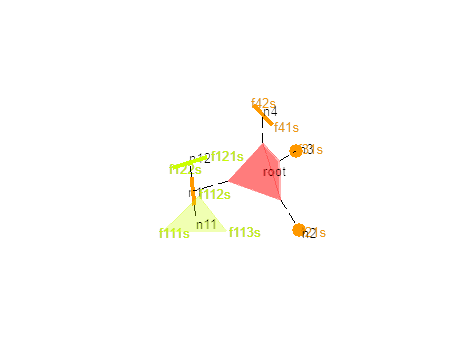

x = interpHierarchical.projection(x);
figure()
interpHierarchical.plot(x);

### b) Scalar field

Each point $x$ is associated to a scalar field value $a$.

a = rand(1,1,n);

## 5) Evaluation of the interpolation

### a) Interpolated value

tic
val = interpHierarchical.eval(x,a); % value
tv1 = toc;
disp(strcat("Compute interpolated values in ",num2str(tv1*1000)," ms"))

Compute interpolated values in 10.0968 ms


### b) Derivative w. r. t. the scalar field

tic
dvalda =  interpHierarchical.evalda(x,a); % derivative w.r.t a
tda1 = toc;
disp(strcat("Compute interpolated a-derivative in ",num2str(tda1*1000)," ms"))

Compute interpolated a-derivative in 6.9129 ms


#### Check the Taylor expansion

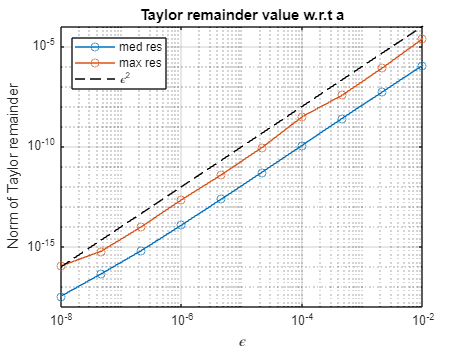

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);

for i=1:10
    pert = epsilon(i)*rand(size(a));
    valPerturbeda = interpHierarchical.eval(x,a+pert);
    res(i,1,:) = vecnorm(valPerturbeda - (val + mult(dvalda,pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t a")
grid on

### c) Derivative w. r. t. the position in the interpolation domain

tic
dvaldx =  interpHierarchical.evaldx(x,a); % derivative w.r.t x
tdx1 = toc;
disp(strcat("Compute interpolated x-derivative in ",num2str(tdx1*1000)," ms"))

Compute interpolated x-derivative in 6.4781 ms


#### Check the Taylor expansion

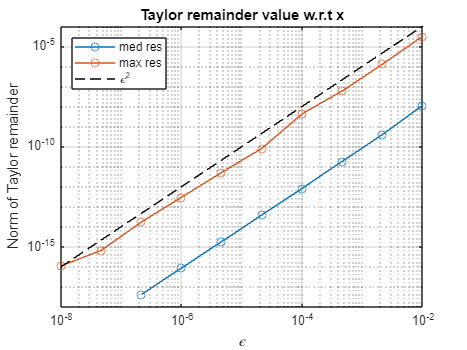

epsilon = logspace(-8,-2,10); % test for different epsilon
allLabel = [interpHierarchical.getAllNodes.Label];
res = zeros(10,length(allLabel),n);

for i=1:10
    for j=1:length(allLabel)
        l=allLabel(j);
        pert = epsilon(i)*rand(size(x.(l)));
        xPert = x;
        xPert.(l) = x.(l) + pert;
        valPerturbedx = interpHierarchical.eval(xPert,a);
        pert = permute(pert,[2,3,1]);
        res(i,j,:) = vecnorm(valPerturbedx - (val + mult(dvaldx.(l),pert)),2,1);
    end
end
MaxRes = max(res,[],[2,3]); medRes = median(res,[2,3]);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t x")
grid on

### d) Speed tip

To compute several times the interpolation for different $a$ without changing the position $x$ in the domain, one should first compute the shape functions once for all.

a2 = rand(100,1,n);
% slow
tic
for i=1:100
    interpHierarchical.eval(x,a2(i,1,:)); % value
    interpHierarchical.evalda(x,a2(i,1,:)); % derivative w.r.t a
    interpHierarchical.evaldx(x,a2(i,1,:)); % derivative w.r.t x
end
tslow = toc;
disp(strcat("Computation time : ",num2str(tslow)," s"))

Computation time : 0.47528 s



% fast
tic
 % pre-computation of the shape functions
[w,dwdx] = interpHierarchical.evalBasisFunction(x);
for i=1:100
    interpHierarchical.eval(x,a2(i,1,:),w); % value
    interpHierarchical.evalda(x,a2(i,1,:),w); % derivative w.r.t a
    interpHierarchical.evaldx(x,a2(i,1,:),w,dwdx); % derivative w.r.t x
end
tfast = toc;
disp(strcat("Computation time : ",num2str(tfast)," s"))

Computation time : 0.22144 s
